6.6   （积分离散数据）实时脚本

由张志涌编写、修改于 2023.1。

x = 1:6

x =      1     2     3     4     5     6


y = [6 8 11 7 5 2]

y =      6     8    11     7     5     2


T = sum(diff(x).*(y(1:end-1)+y(2:end))/2)

T =     35


u=1:0.1:6;
v=spline(x,y,u);
Qs=trapz(u,v)

Qs =   35.247500000000002


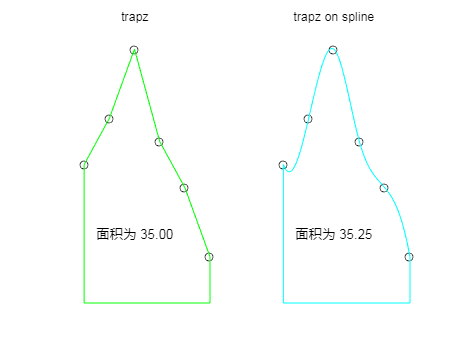

clf
set(gcf,'Color','w')
subplot(1,2,1)
plot(x,y,'ok',x,y,'-g')
hold on
plot([x(1),x(1),x(6),x(6)],[y(1),0,0,y(6)],'-g')
hold off
text(3,3,['面积为 ',num2str(T,'%.2f')],...
    'HorizontalAlignment','center')
axis off
ylim([0,12])
title('trapz')
subplot(1,2,2)
plot(x,y,'ok',u,v,'c-')
hold on
plot([x(1),x(1),x(6),x(6)],[y(1),0,0,y(6)],'-c')
hold off
text(3,3,['面积为 ',num2str(Qs,'%.2f')],...
    'HorizontalAlignment','center')
axis off
ylim([0,12])
title('trapz on spline')